# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: 

- Location: Locomotion Laboratory

- Subject: 

- Quarq calibration factor: 

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 20.9

- Humidity (%): 33.6

- Pressure (mmHg): 635           

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 5;
code = {'EG'};
sex = {'M'};
age = 30;
mass = 148; %lb
height = 1.78; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    number     code      sex     age    mass    height
    ______    ______    _____    ___    ____    ______

      5       {'EG'}    {'M'}    30     148      1.78 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.05; 0.1; 0.18];
listHang = listPerc * mass

listHang =     7.4000
   14.8000
   26.6400


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

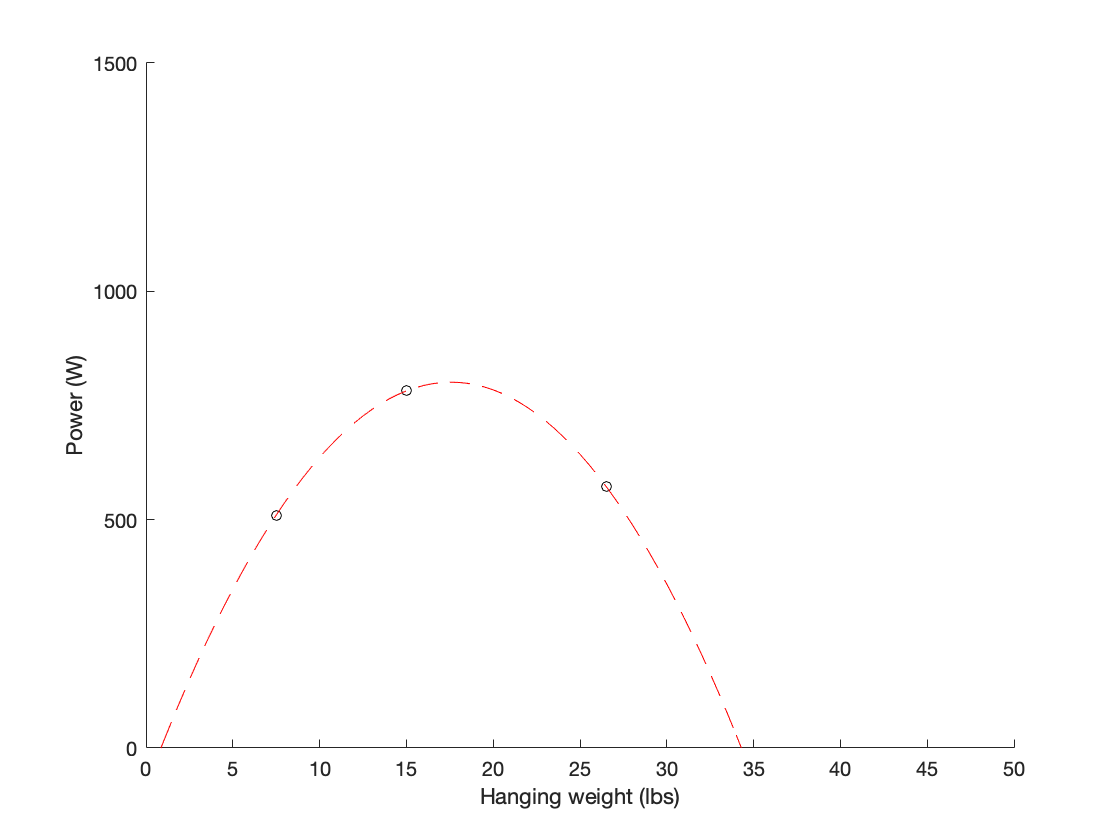

x = [7.5; 15; 26.5]; % hanging weight
x_ = [156; 115; 48]; % cadence
y = [510; 782; 573]; % power output

% fit curve: power vs hang
% [c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);
[c, ~, ~] = fit(x,y,'poly2');

new_x = 0:50/100:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r--')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 801.03 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 17.50 Lbs 


### Randomize trial order within each block

randperm(3)
randperm(3)
randperm(3)

### Experimental results

Record results to array then convert to table.

data = [
    5, 1, 1, 17.5, 908, 105;
    5, 2, 1, 17.5, 787, 96;
    5, 3, 1, 17.5, 808, 100;
    5, 3, 2, 17.5, 829, 103;
    5, 1, 2, 17.5, 859, 104;
    5, 2, 2, 17.5, 683, 92;
    5, 2, 3, 17.5, 774, 99;
    5, 3, 3, 17.5, 821, 103;
    5, 1, 3, 17.5, 899, 106;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       5           1          1          17.5          908       105  
       5           2          1          17.5          787        96  
       5           3          1          17.5          808       100  
       5           3          2          17.5          829       103  
       5           1          2          17.5          859       104  
       5           2          2          17.5          683        92  
       5           2          3          17.5          774        99  
       5           3          3          17.5          821       103  
       5           1          3          17.5          899       106  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           888.67            105   
        2            3              748         95.667   
        3            3           819.33            102   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          26.083             1   
        2            3          56.666        3.5119   
        3            3          10.599        1.7321   
